# Lab B: Constructing Basic Graph Matrices 2

## Part 1 Prelab Review: Weighted Node-Edge Incidence Matrix and Cycles

### **Example: **

*Please examine the simple graph below and make sure you understand what the **edge weights** are and how to interpret them -- you should know this if you completed the prelab!*

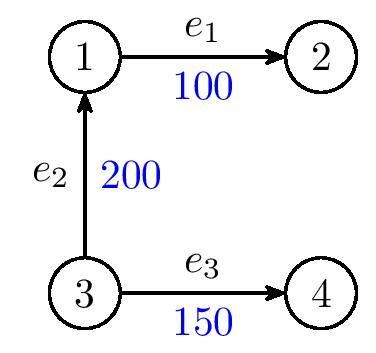


$$\bar{A} = AW = \pmatrix{1 & -1 & 0 \cr -1 & 0  & 0 \cr 0 & 1 & 1 \cr 0 & 0 & -1}\pmatrix{100 & 0 & 0 \cr 0 & 200 & 0 \cr 0 & 0 & 150} = \pmatrix{100 & -200 & 0 \cr -100 & 0 & 0 \cr 0 & 200 & 150 \cr 0 & 0 & -150}$$


#### Question 1.1 

Is there a cycle in the graph above? If so, how many? 

*————————————————————————————————*

*Your answer: ***the graph does not have any cycles.**

*————————————————————————————————*

### **Exercise: Construct the *****Weighted*** Node-Edge Incidence Matrix $\bar{A}$ for the following graphs and display the results: 

#### Question 1.2

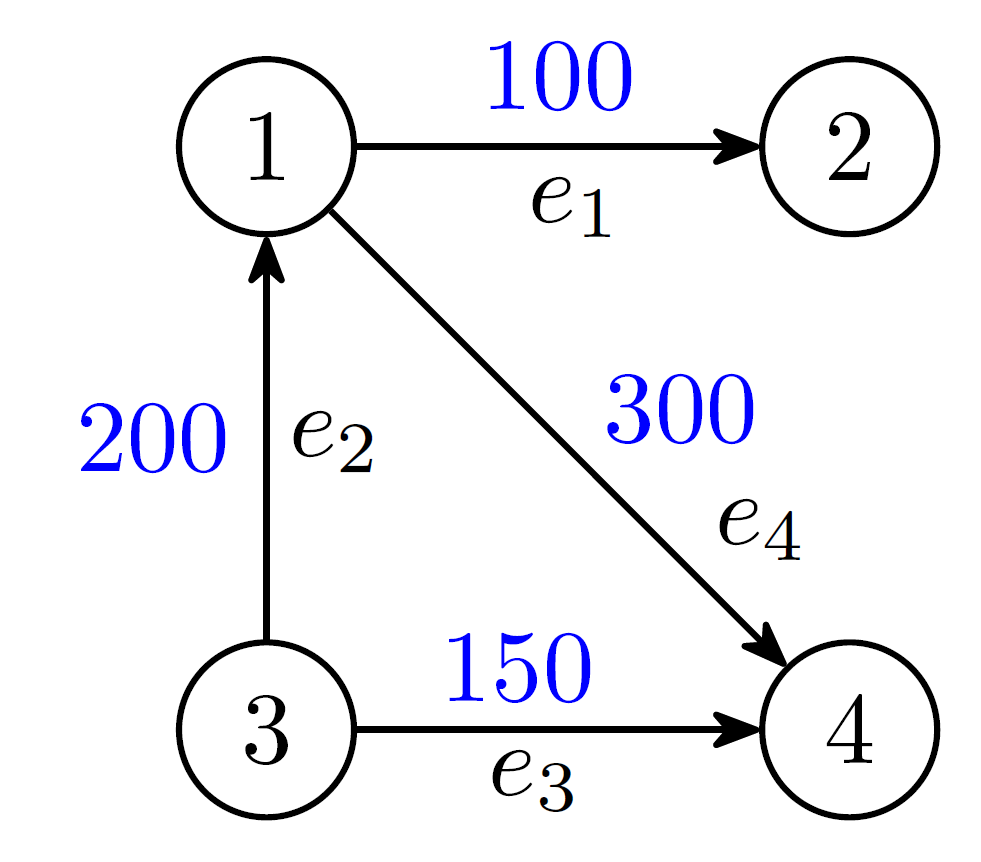 

The edge weights for this graph are $w_1 = 100, w_2 = 200, w_3 = 150, w_4 = 300$.

% your code here
A1 = [[1;-1;0;0] [-1; 0; 1; 0] [0; 0; 1; -1] [1; 0; 0; -1]];
W1 = diag([100,200,150,300]);
A1_weighted = A1*W1

A1_weighted =    100  -200     0   300
  -100     0     0     0
     0   200   150     0
     0     0  -150  -300


#### Question 1.3

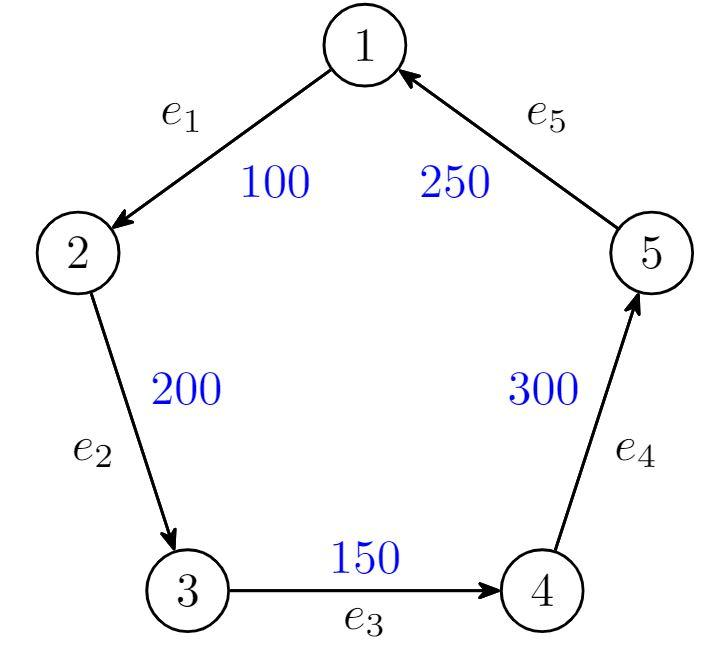

The edge weights are $w_1 = 100, w_2 = 200, w_3 = 150, w_4 = 300, w_5 = 250$.

% your code here
A2 = [[1;-1;0;0;0] [0;1;-1;0;0] [0;0;1;-1;0] [0;0;0;1;-1] [-1;0;0;0;1]];
W2 = diag([100,200,150,300,250]);
A2_weighted = A2*W2

A2_weighted =    100     0     0     0  -250
  -100   200     0     0     0
     0  -200   150     0     0
     0     0  -150   300     0
     0     0     0  -300   250


## Part 2 **Construction of the Edge-Cycle Incidence Matrix **

We now introduce the final graph matrix in this topic: the ***edge-cycle incidence matrix ***$C$. Unlike the graph matrices previously introduced, $C$ is never a square matrix. We will also examine its relationship to $A$. 

First, we discuss how the edge-cycle incidence matrix $A$ is constructed element-wise: recall from the prelab that we can write a cycle as a sequence of edges $e_i$. In vector form, we can also write it as 


$$c = \pmatrix{\delta_1 \cr \delta_2 \cr \vdots \cr \delta_m} \in \mathbb{R}^m,$$


where 

- $\delta_i = 1$ if $e_i$ is in the cycle and has the **same direction** as the cycle, 

- $\delta_i = -1$ if $e_i$ is in the cycle but has the **opposite direction** as the cycle, 

- $\delta_i = 0$ if $e_i$ is **not in the cycle**

### Example:

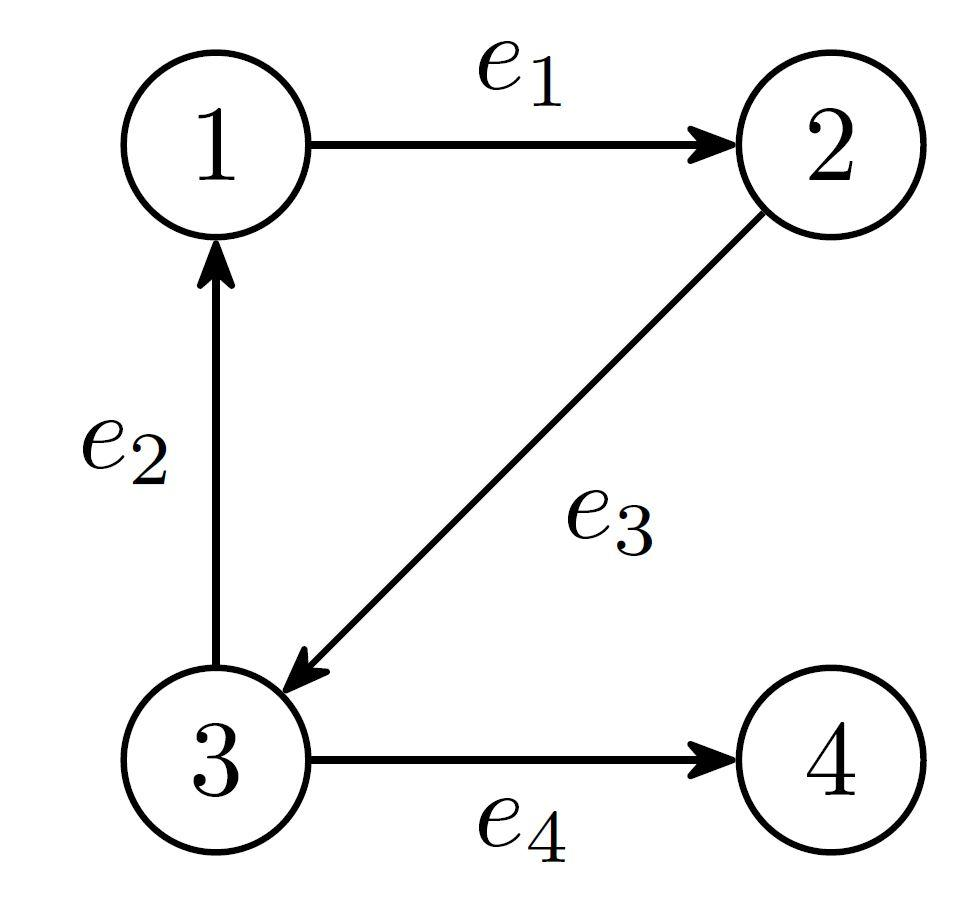

For the graph above, **if we pick the direction of the cycle to be clockwise**, then the edges in the cycle have the **same** direction, so

$c = \pmatrix{1 \cr 1 \cr 1 \cr 0}$.

However, **if we pick the direction of the cycle to be counterclockwise**, then the edges have the **opposite **direction, so

$c = \pmatrix{-1 \cr -1 \cr -1 \cr 0}$.

In this graph, there is only one cycle, but if there are more, then we can construct the $c_1, c_2, ...$ vectors for all the cycles. 

**To construct the Edge-Cycle Incidence Matrix **$C$**, we simply** **find all the cycle vectors **$c_i$, **and put them as the column vectors of **$C$. 

However, **these column vectors must be linearly independent**! That is, if we have more than one cycles in a graph, it is possible for some of the cycles to be constructed from smaller/other cycles, i.e., they are **dependent** on these smaller/other cycles. We do not use any cycle vectors that are depedent on other cycles in the construction of $C$. 

Now, we are ready to do some exercises! 

### Exercise: Construct the Edge-Cycle Incidence Matrix and display the results

#### Question 2.1

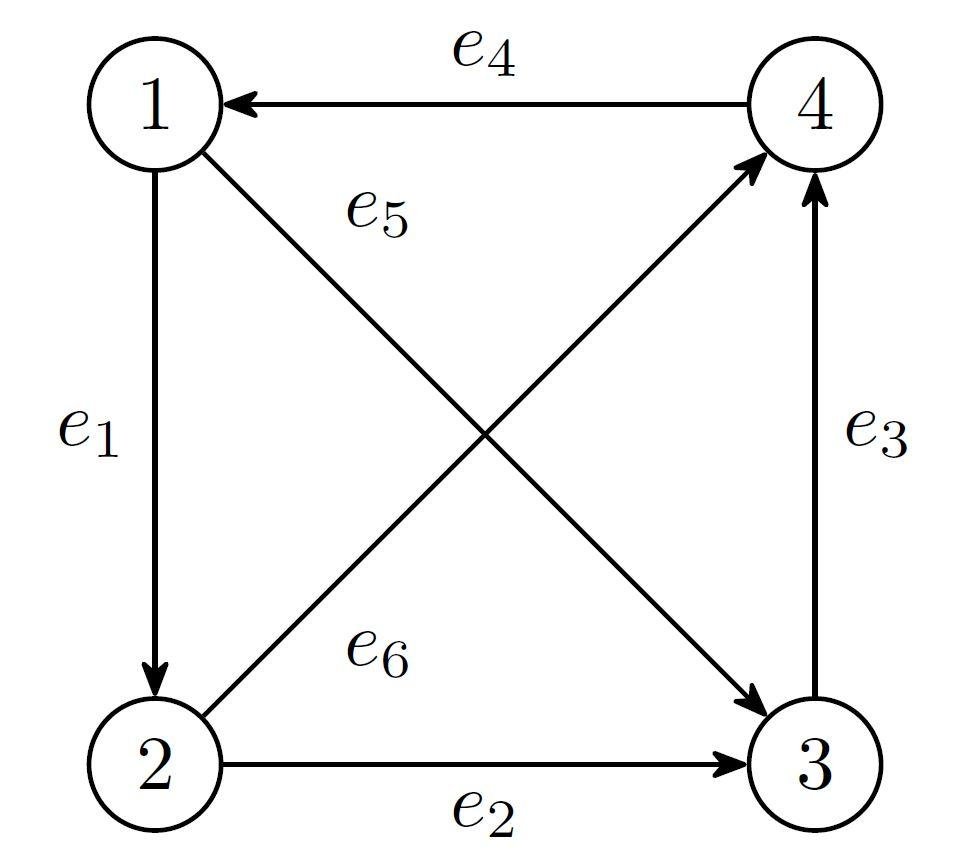

For this graph (and this graph only), we provide you with the information that there are only 3 independent cycles. Suppose the cycle directions are all counterclockwise. You may use the fact that the first independent cycle is $\{e_1, e_2, -e_5\}$ (again, the negative sign implies the edge direction is opposite to the cycle direction), the second independent cycle is $\{e_2, e_3, -e_6\}$, and the third independent cycle is $\{e_3, e_4, e_5\}$. First construct the cycle vectors `c1, c2, c3`, and then construct the matrix $C$. 

% your code here
c1 = [1;1;0;0;-1;0];
c2 = [0;1;1;0;0;-1];
c3 = [0;0;1;1;1;0];
% construct the edge-cycle matric C based on c1, c2, c3
C1 = [c1 c2 c3]

C1 =      1     0     0
     1     1     0
     0     1     1
     0     0     1
    -1     0     1
     0    -1     0


#### Question 2.2

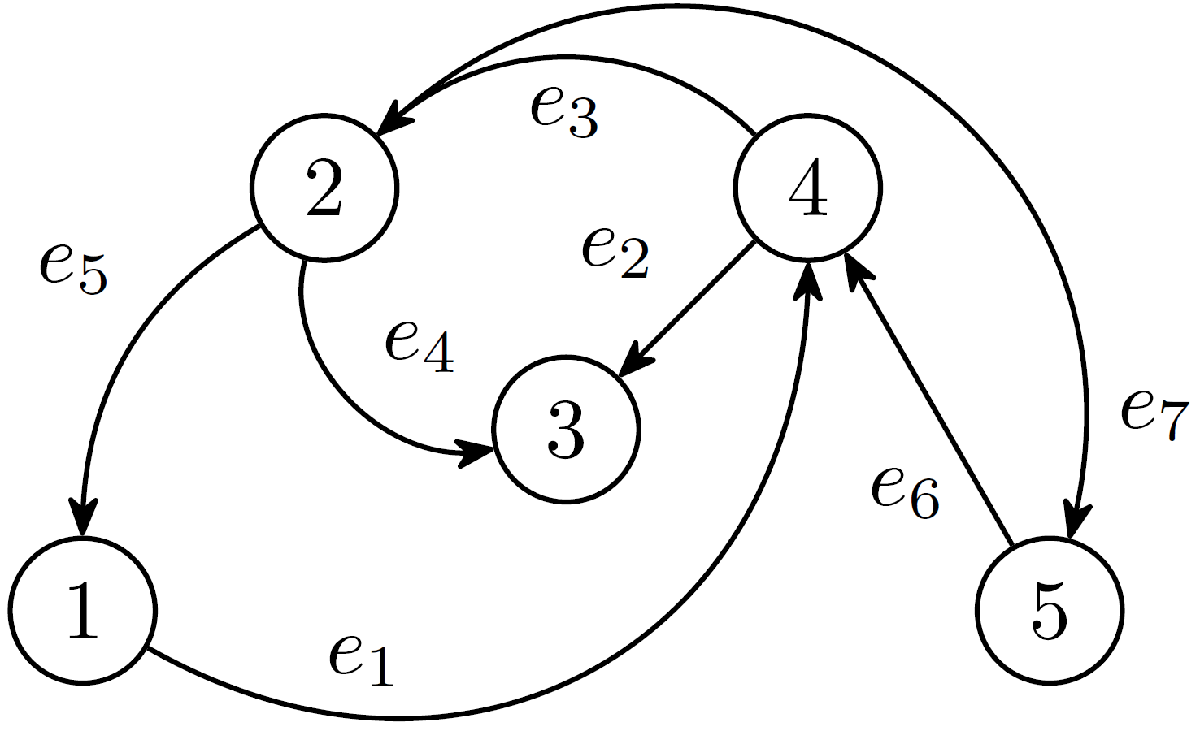

Now, we will not supply the detailed instruction like before, and you can try to figure out how many independent cycles there are, construct the cycle vectors, and the $C$ matrix. (Hint: review one of the exercise questions from last week.)

% your code here

% we can create a C matrix with all possible cycles in the graph and then
% find its rank to determine how many independent cycles there are (since
% the redundant columns would not having leadings 1s because they are
% dependent cycles):
C2_all = [[1;0;1;0;1;0;0] [0;-1;1;1;0;0;0] [0;0;-1;0;0;-1;-1] [1;1;0;-1;1;0;0] [1;0;0;0;1;-1;-1] [0;-1;0;1;0;-1;-1]];
rank(C2_all)

ans = 3

% since the rank is 3, there must be 3 independent cycles
C2 = [[1;0;1;0;1;0;0] [0;-1;1;1;0;0;0] [0;0;-1;0;0;-1;-1]]

C2 =      1     0     0
     0    -1     0
     1     1    -1
     0     1     0
     1     0     0
     0     0    -1
     0     0    -1


## Part 3: Simple Properties of Edge-Cycle Incidence Matrix 

#### **Question 3.1**

Let the total number of **independent** cycle vectors be $n_c$, and let there be $n$ total nodes and $m$ total edges in the graph. What is the dimension of $C$? How about $\mathrm{rank}(C)$? Write your answer in terms of $n, m$, and $n_c$. 

*————————————————————————————————*

*Your answer: *$\dim \left(C\right)=m-n+1$; $\textrm{rank}\left(C\right)=n-1$

*————————————————————————————————*

#### **Question 3.2**

Refer back to the two graphs in Exercise 2, what do you notice about the number of nodes $n$, the number of edges $m$, and the total number of indepdent cycles $n_c$? Can you write an equation that involves all three variables? 

(Hint: think about the size of the *node-edge incidence matrix *and its rank, which is given in the prelab. You can check its rank by using the `rank` command on MATLAB.) 

% Your code, if you need it

*————————————————————————————————*

*Your answer: *$n_c =m-n+1$

*————————————————————————————————*

#### **Question 3.3**

Construct the **node-edge incidence matrix **$A$ for the graphs in Exercise 2 as well (you did this last week!), and compute the product $AC$. What do you notice about the result? 

% Your code here
A1 = [[1;-1;0;0] [0;1;-1;0] [0;0;1;-1] [-1;0;0;1] [1;0;-1;0] [0;1;0;-1]];
A2 = [[1;0;0;-1;0] [0;0;-1;1;0] [0;-1;0;1;0] [0;1;-1;0;0] [-1;1;0;0;0] [0;0;0;-1;1] [0;1;0;0;-1]];

disp(A1*C1);

     0     0     0
     0     0     0
     0     0     0
     0     0     0



disp(A2*C2);

     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



*————————————————————————————————*

*Your observation: ***both products AC equal 0 (i.e. have all entries equal to 0)**

*————————————————————————————————*

#### **Question 3.4**

Recall the command introduced last week: for a matrix $M$ (a particular example is shown here), the command

M = [1 0 -1; -1 1 0; 0 -1 1];
null(M, 'r')

ans =      1
     1
     1


gives the *rational basis* for $\mathrm{ker}(M)$. You already computed the rational basis for the $A$ matrix in the graphs in Exercise 2 last week. Repeat those steps, and display the results here:

% Your code
disp(null(A1, 'r'));

     1    -1     0
     1    -1    -1
     1     0    -1
     1     0     0
     0     1     0
     0     0     1



disp(null(A2, 'r'));

     0     1     0
    -1     0     0
     1     1     1
     1     0     0
     0     1     0
     0     0     1
     0     0     1



Can the column vectors in the result for each graph be interpreted as a cycle vector? If yes, give an example on how to turn one such cycle vector in your result into the "sequence of edges in a cycle" as in the prelab.  

*————————————————————————————————*

*Your answer: ***Yes, the column vectors in the result for each graph can be interpreted as a cycle vector. For example, for the 1st column in ker(A2), the parity (i.e. +/- sign) of the entries matches up with the CCW direction, so that column can be the 1st column vector in C. For subsequent vectors, if the parity of the entries does not match up with the same direction, all entries of the specific column vector can be multiplied by -1 (like with the 3rd column vector in ker(A2)) so the direction of the cycle matches that of the other cycles.**

*————————————————————————————————*

#### **Question 3.5**

Let $\mathbf{0}$ denote the matrix with all-zero entries. Based on your answers in Exercise 3 Part 3, can you write an equation involving $A, C$, and $\mathbf{0}$? 

*————————————————————————————————*

*Your answer: *$\textrm{AC}=0$.

*————————————————————————————————*

How about an equation using the **weighted** node-edge incidence matrix $\bar{A}$ and the edge weight matrix $W$,  the edge-cycle incidence matrix $C$, and $\mathbf{0}$? Justify your answer in one sentence, or verify your answer on MATLAB. 

(Hint: the inverse of $W$ is simply the diagonal matrix whose diagonal entries are $\frac{1}{w_1}, \frac{1}{w_2}, \cdots, \frac{1}{w_m}$, and $W$ is always invertible since its determinant is never $0$ when we require that $w_i > 0$ for all $i = 1, 2, ..., m$.)

*————————————————————————————————*

*Your answer: *$\bar{A}W^{-1}C = 0$

*————————————————————————————————*

% Your code, to verify that your answer is true:

% set arbitrary weights for graph 2 (specific values are irrelevant as long
% as we are consistent with evaluating A2_weighted and W^-1)
W2 = diag([1,2,3,4,5,6,7]);
A2_weighted = A2*W2;
A2_weighted*inv(W2)*C2

ans =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
